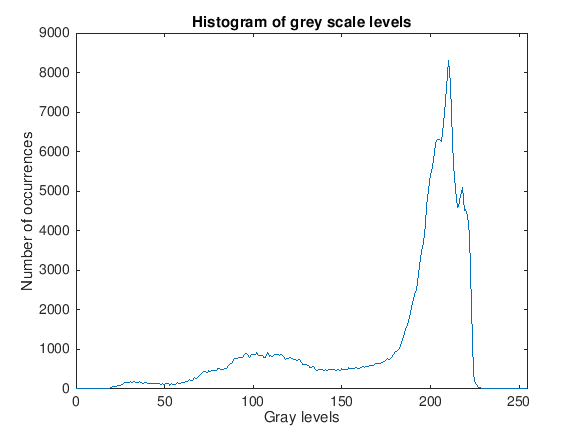

A = double(imread("Image_2.png"));

% Histogram %
[N, edges] = histcounts(A, 0:256);
plot(0:255, N);
title('Histogram of grey scale levels');
xlabel('Gray levels');
ylabel('Number of occurrences');
xlim([0 255]);


% Entropy %
probabilities = N/sum(N);
probabilities = probabilities(probabilities>0);
H = -sum(probabilities.*log2(probabilities))

H = 6.7025

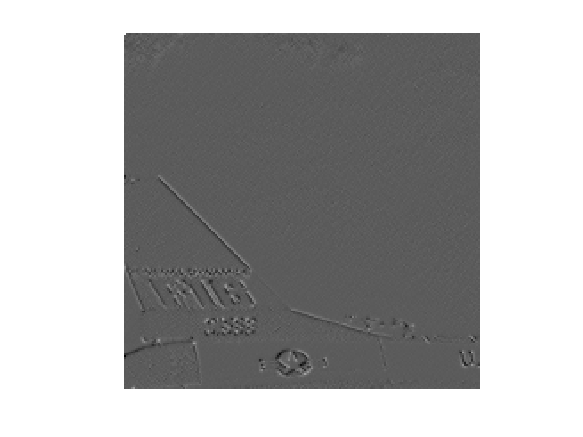


% Cropping image %
B = A(50:249,50:249);
imwrite(uint8(B),'MyImage_2.png','png');
nr = 200;
nc = 200;

E = zeros(nr,nc);
Evertcat = [];
for j=1:nc
    for i=1:nr
        causalNeighborhood = [];
        if i > 1
            causalNeighborhood = [causalNeighborhood, B(i-1, j)];
        end
        if j > 1
            causalNeighborhood = [causalNeighborhood, B(i, j-1)];
        end
        if i > 1 && j > 1
            causalNeighborhood = [causalNeighborhood, B(i-1, j) + B(i, j-1) - B(i-1, j-1)];
        end
        if i == 1 && j == 1
            causalNeighborhood = [0];
        end
        E(i,j) = B(i,j) - median(causalNeighborhood);
    end
    % Concatening every column
    Evertcat = vertcat(Evertcat, E(:,j));
end

imshow(E,[]); %Displaying matrice, minimum is black, maximum is white


% Looking for optimal L, optimal p %
L = (50:50:2000);
L = [L, 200*200]; %Append to also compute one block option
CL = [];

best_size = 1e10;
best_p = 1;
best_L = 1;

for block_size_idx = 1:size(L, 2)
    block_size = L(block_size_idx);
    nb_blocks = ceil(size(Evertcat,1) / block_size);
    total_size = 0;
    optimals_p = [];
    
    for i = 1:nb_blocks
        % Last block must be troncated
        block = Evertcat(1 + (i-1)*block_size : min(i*block_size, nr*nc));
        optimal_block_size = 1e10;
        optimal_block_p = 1;
        % Looking for optimal p %
        for p = 1:16
            bsize = GRestimation(block, p);
            if bsize < optimal_block_size
                optimal_block_size = bsize;
                optimal_block_p = p;
            end
        end
        optimals_p = [optimals_p, optimal_block_p];
        total_size = total_size + optimal_block_size;
    end
    % Final size is sum of optimal block sizes + encoding optimal p %
    % Each p value can be transmitted using the number of bits needed to encode the maximum value p %
    p_encoding_size = floor(log2(max(optimals_p))) + 1;
    if block_size < nr*nc
        final_size = total_size + nb_blocks * p_encoding_size;
        CL = [CL, final_size];
        if final_size < best_size 
            best_size = final_size;
            best_p = optimals_p;
            best_L = block_size;
        end
    else
        size_no_segmentation = total_size
    end
end

size_no_segmentation = 174748

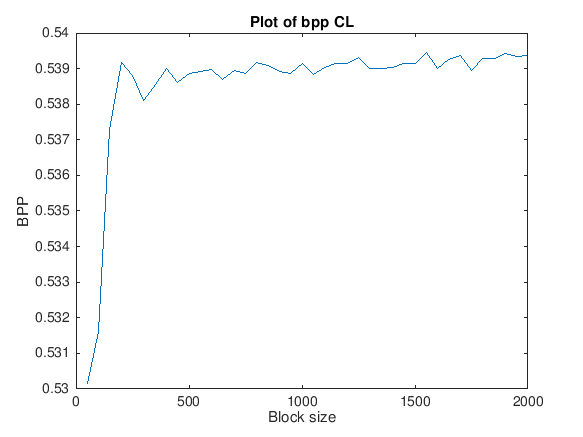


L = L(1:length(L)-1);
bpp_CL = CL / (8*200*200);
plot(L,bpp_CL);
title('Plot of bpp CL');
xlabel('Block size');
ylabel('BPP');


% Compression %

best_L

best_L = 50

best_p

best_p =      2     2     2     2     1     1     2     1     1     1     2     1     1     1     2     1     1     1     2     2     1     1     2     2     1     1     2     1     1     1     2     2     1     1     2     2     1     1     1     2     1     1     2     3     1     1     1     2     1     1


best_size

best_size = 169647

compressed_bits = [];
nb_blocks = ceil(size(Evertcat,1) / best_L);

for i = 1:nb_blocks
    p = best_p(i);
    block = Evertcat(1 + (i-1)*best_L : min(i*best_L, 200*200));
    
    for intgr_idx = 1:length(block)
        intgr = block(intgr_idx);
        if intgr < 0; sign = 1; intgr = -intgr; else; sign = 0; end
        least_significant = mod(intgr, 2^p);
        least_significant_binary = fliplr(de2bi(least_significant));
        most_significant = floor(intgr / 2^p);
        most_significant_unary = [zeros(1, most_significant), 1];
        
        compressed_bits = [compressed_bits, sign];
        n = 0;
        while n < (p - length(least_significant_binary))
            compressed_bits = [compressed_bits, 0];
            n = n + 1;
        end
        compressed_bits = horzcat(compressed_bits, least_significant_binary);
        compressed_bits = horzcat(compressed_bits, most_significant_unary);
    end
end

size_compressed = length(compressed_bits) + (floor(log2(max(best_p))) + 1)*(nb_blocks)

size_compressed = 169647


fid = fopen('compressed_file', 'w');
fwrite(fid, compressed_bits, 'ubit1');